Import Dataset

close all;
clear all;
inputTable = readtable("../data/Concrete_Data.csv");


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
predictorNames = inputTable.Properties.VariableNames(1,1:8);
predictors = inputTable(:, predictorNames);
response = inputTable.Concrete_Compressive_Strength_Mpa;

%Print out head of table
display(inputTable(1:10,:))

  10×9 table

    Cement_kgm_3    BlastFurnaceSlag_kgm_3    FlyAshkgm_3    Water_kgm_3    Superplasticizer_kgm_3    CoarseAggregate_kgm_3    FineAggregate_kgm_3    Age_days    Concrete_Compressive_Strength_Mpa
    ____________    ______________________    ___________    ___________    ______________________    _____________________    ___________________    ________    _________________________________

         540                    0                  0             162                 2.5                       1040                     676              28                    79.986              
         540                 

Build box plot of dataset - standard EDA activities to gain an understanding of what the dataset looks like

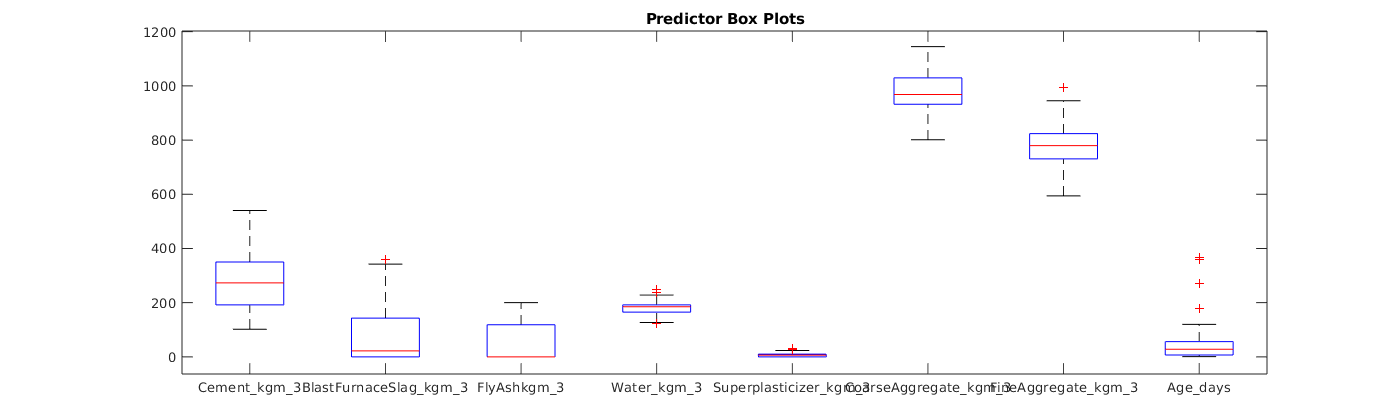

boxplot(table2array(predictors),'Labels',predictorNames);
h = gcf;
h.Position(3) = h.Position(3)*2.5;
title('Predictor Box Plots');

Next we generate a cross-correlation plot for all features and the response variable. A correlation matrix has also been generated. These can be used to infer which of our features may be good for infering our response variable. Variables that strongly correlate with the response variable are likely good indicatiors whist variables that strongly correlate with other variables are likely to contain shared information. In this case a decision could be made to remove one of these features from the model.

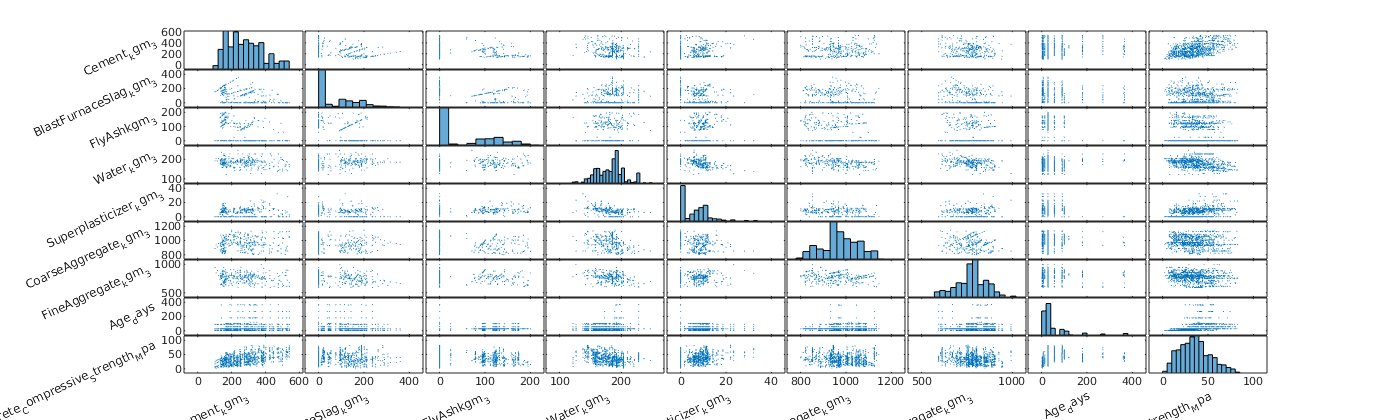

%Create a pairplot to look at cross-correlation
[~,ax] = plotmatrix(table2array(inputTable));
plotSize =width(inputTable);
for k=1:plotSize
ax(k,1).YLabel.String = inputTable.Properties.VariableNames{1,k}; 
ax(k,1).YLabel.Rotation = 25;
ax(k,1).YLabel.HorizontalAlignment = 'right';
ax(plotSize,k).XLabel.String = inputTable.Properties.VariableNames{1,k};
ax(plotSize,k).XLabel.Rotation = 25;
ax(plotSize,k).XLabel.HorizontalAlignment = 'right';

end


%we can also compute the correlation between all features including the response variable 
correlationMatrix = corr(table2array(inputTable));
display(correlationMatrix)

correlationMatrix =     1.0000   -0.2752   -0.3975   -0.0815    0.0928   -0.1094   -0.2227    0.0819    0.4978
   -0.2752    1.0000   -0.3236    0.1073    0.0434   -0.2840   -0.2816   -0.0442    0.1348
   -0.3975   -0.3236    1.0000   -0.2570    0.3773   -0.0100    0.0791   -0.1544   -0.1058
   -0.0815    0.1073   -0.2570    1.0000   -0.6575   -0.1823   -0.4506    0.2776   -0.2896
    0.0928    0.0434    0.3773   -0.6575    1.0000   -0.2663    0.2225   -0.1927    0.3661
   -0.1094   -0.2840   -0.0100   -0.1823   -0.2663    1.0000   -0.1785   -0.0030   -0.1649
   -0.2227   -0.2816    0.0791   -0.4506    0.2225   -0.1785    1.0000   -0.1561   -0.1672
    0.0819   -0.0442   -0.1544    0.2776   -0.1927   -0.0030   -0.1561    1.0000    0.3289
    0.4978    0.1348   -0.1058   -0.2896    0.3661   -0.1649   -0.1672    0.3289    1.0000


Lets also apply T-SNE to allow us to visualise a 2D map of the dataset

T-SNE creates a non-linear mapping between the high-dimentional dataset and the 2D visual where data points that are close in the high-dimentional space are close within the 2D map. The axis of the map do not have a specific meaning or orientation plus T-SNE is non-convex meaning that different runs converge to different solutions. Therefore we perform T-SNE 3 times and inspect for consistencies. The intuition is that similaries between the plots may indicate structure within the dataset. We also map the response variable as the hue of a data point. This is useful for understanding that within our high-dimentional dataset, there are non-linear structures and moreover data points with similar values for the response variable tend to be neighbours within the high-dimentional space. 

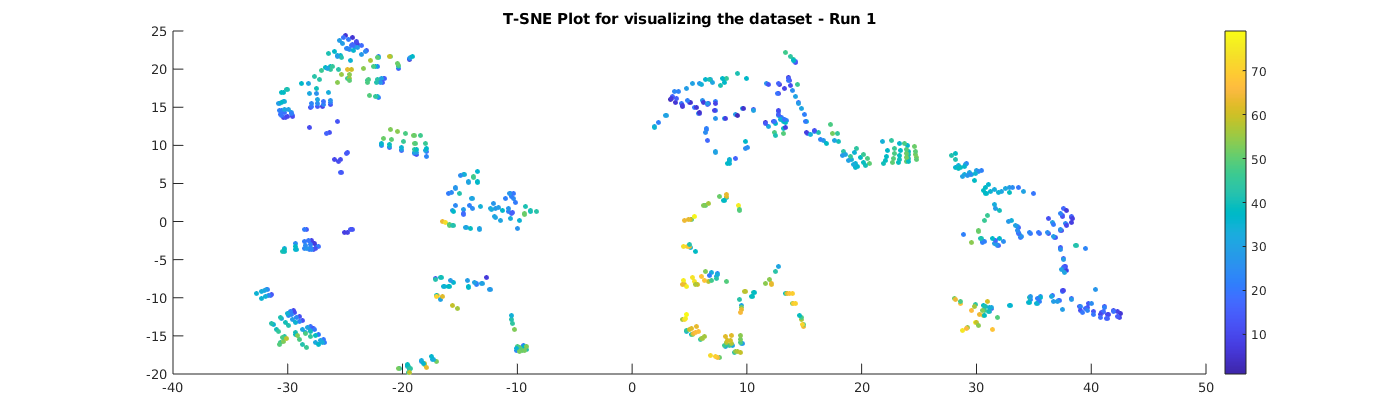

%Apply Stochastic Neighbour Embedding for Visualization of the Raw data
Y = tsne(table2array(predictors),'Distance', "cosine",'Standardize',true,"Perplexity",30);
bins =  floor(max(response)) - ceil(min(response));
scatter(Y(:,1),Y(:,2),15,discretize(response,bins),"filled");
colorbar;
title("T-SNE Plot for visualizing the dataset - Run 1");

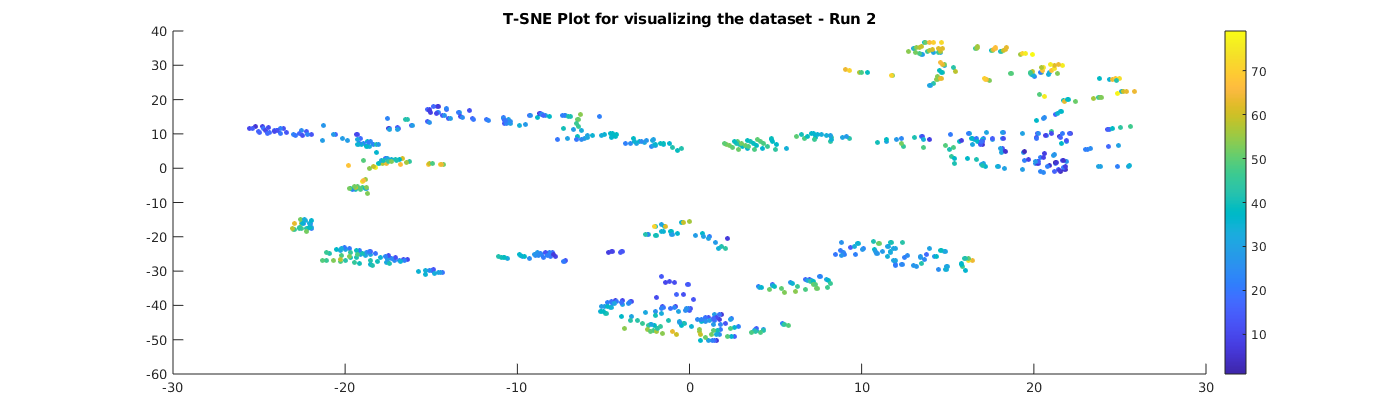

%Apply Stochastic Neighbour Embedding for Dimentionality Reduction
Y = tsne(table2array(predictors),'Distance', "cosine",'Standardize',true,"Perplexity",30);
scatter(Y(:,1),Y(:,2),15,discretize(response,bins),"filled");
colorbar;
title("T-SNE Plot for visualizing the dataset - Run 2");

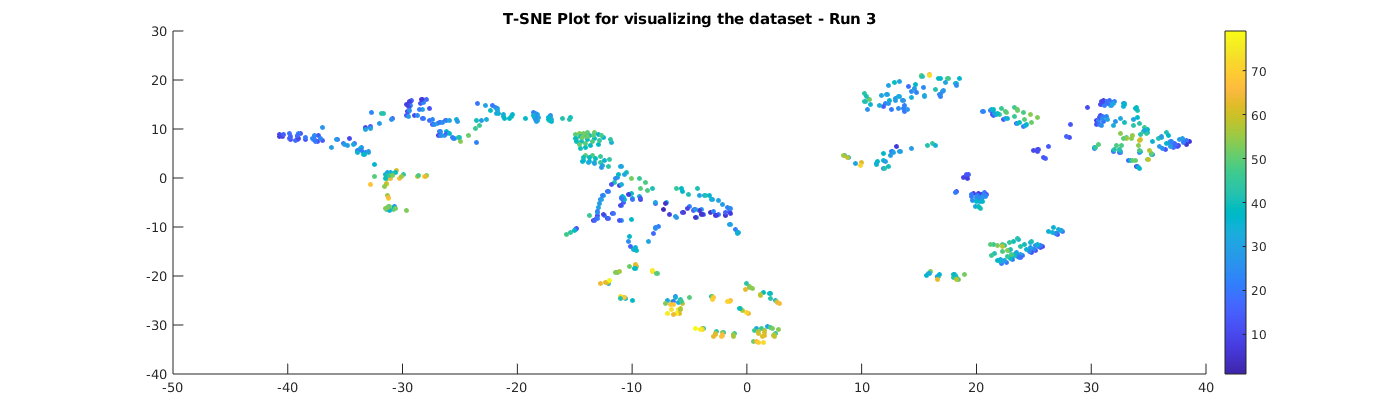

%Apply Stochastic Neighbour Embedding for Dimentionality Reduction
Y = tsne(table2array(predictors),'Distance', "cosine",'Standardize',true,"Perplexity",30);
scatter(Y(:,1),Y(:,2),15,discretize(response,bins),"filled");
colorbar;
title("T-SNE Plot for visualizing the dataset - Run 3");

To predict the response variable, we are going to look at 2 models: EnsembleTree and Gaussian Processes. We can use the built in Matlab functions for these and we also want to leverage cross-validation to gain a better understanding of how well our model generalizes. Finally we also want to leverage the "bayesopt" bayesian optimization methods for model hyperparameter tuning and model selection. These can be accessed through the matlab functions but we may need to come back and configure limits for Bayesian Hyperparameter Optimization. That is what this section break is for.

%Use params = hypermparameters() to set limits for hyperparameter Optimization


Train RandomForest Model and perform Model Selection

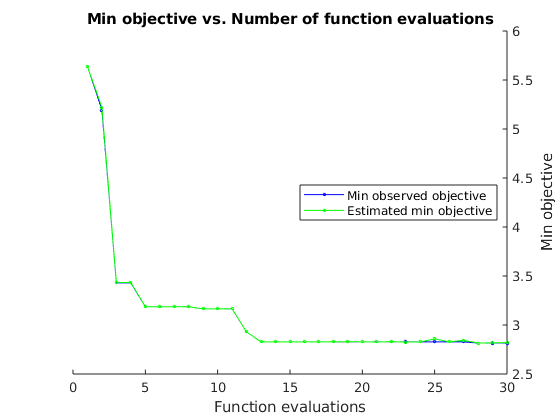

|=================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | NumVariables-|
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | ToSample     |
|=================================================================================================================================================================|
|    1 | Best   |      5.6374 |      9.1558 |      5.6374 |      5.6374 |          Bag |          323 |            - |          492 |           38 |            5 |
|    2 | Best   |       5.193 |      1.0748 |       5.193 |      5.2209 |          Bag |           32 |            - |          131 |           67 |            1 |
|    3 | Best   

%Optimize Model Hyperparameters using bayesian inference (bayesopt)
%EnsembleTree
template = templateTree('Reproducible', true,'Surrogate','on');
regressionEnsemble = fitrensemble(predictors, response, ...
    'Learners', template, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

Train Gaussian Processes Model and perform Model Selection

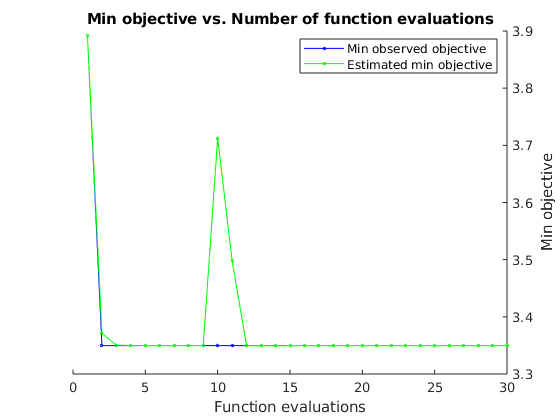

|==================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma | BasisFunction| KernelFuncti-|  KernelScale |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |      3.8916 |      10.788 |      3.8916 |      3.8916 |    0.0001019 |       linear | squaredexpon |       350.55 |         true |
|    2 | Best   |      3.3496 |      2.9112 |      3.3496 |      3.3711 |       3.7706 | pureQuadrati |     matern52 |       324.69 |        false |
|    3 | Accept |      3.6888 |      10.133 |      3.3496 |      3.3504 |      0.65494 |       linear | ra

%Gaussian Process Regressor
% Blog post of what a gaussian process model is: https://towardsdatascience.com/an-intuitive-guide-to-gaussian-processes-ec2f0b45c71d
regressionGP = fitrgp(predictors, response, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

Although we performed cross-validation in the model selection steps above, we want to perform cross-validation to calculate the validation error for the purpose of model comparison. We therefore take the best EnsembleTree and GaussianProcess models and predict the kFoldLoss. This gives us a consistent manor to compare our two tuned models.

%Cross Validation Settings
crossValidationMethod = 'KFold';
crossValidationNumFolds = 5;
crossValidationLossFun = 'mse';

% Perform cross-validation
partitionedModel_RF = crossval(regressionEnsemble, crossValidationMethod, crossValidationNumFolds);
partitionedModel_GP = crossval(regressionGP, crossValidationMethod, crossValidationNumFolds);

% Compute validation predictions
validationPredictions_RF = kfoldPredict(partitionedModel_RF);
validationPredictions_GP = kfoldPredict(partitionedModel_GP);

% Compute validation RMSE
validationRMSE_RF = sqrt(kfoldLoss(partitionedModel_RF, 'LossFun', crossValidationLossFun))

validationRMSE_RF = 4.0370

validationRMSE_GP = sqrt(kfoldLoss(partitionedModel_GP, 'LossFun', crossValidationLossFun))

validationRMSE_GP = 5.3497

Save the Trained Models and Model Selection Plots.

%save trained models and figures 1 & 2
%save("trainedModels/regressionEnsemble","regressionEnsemble","validationRMSE_RF");
%save("trainedModels/regressionGP","regressionGP","validationRMSE_GP");
%saveas(figure(3),'trainedModels/regressionEnsemble_hyperparameter_tuning.png');
%saveas(figure(4),'trainedModels/regressionGP_hyperparameter_tuning.png');

With EnsembleTree we can look to understand the feature Importance.

[imp,ma] = predictorImportance(regressionEnsemble)

imp =     0.0111    0.0029    0.0020    0.0041    0.0045    0.0018    0.0028    0.0151


ma =     1.0000    0.0205    0.0217    0.0163    0.0131    0.0197    0.0177    0.0020
    0.0317    1.0000    0.0217    0.0184    0.0187    0.0154    0.0220    0.0039
    0.0346    0.0232    1.0000    0.0340    0.0341    0.0212    0.0234    0.0047
    0.0168    0.0132    0.0163    1.0000    0.0359    0.0205    0.0194    0.0036
    0.0218    0.0145    0.0287    0.0426    1.0000    0.0201    0.0154    0.0038
    0.0181    0.0184    0.0180    0.0188    0.0132    1.0000    0.0225    0.0020
    0.0186    0.0160    0.0134    0.0261    0.0111    0.0243    1.0000    0.0021
    0.0020    0.0018    0.0007    0.0056    0.0035    0.0025    0.0031    1.0000


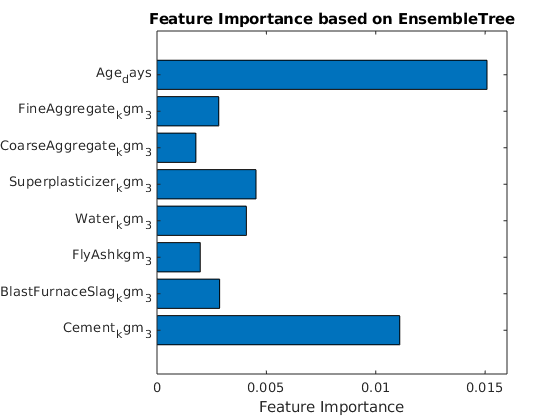

barh(imp);
yticklabels(predictorNames)
xlabel("Feature Importance")
title("Feature Importance based on EnsembleTree")

We can see that 5 for the features are more important than the others. Lets try training again with these 5 most important features, perform xval and evaluate results. 

%Select the top important features and train both models again
topImportantFeatures = 6;
[kImp,I] = maxk(imp,topImportantFeatures);
topKpredictors = inputTable(:, I);
topKpredictorNames = predictorNames(I)

topKpredictorNames = 1×6 cell array
    {'Age_days'}    {'Cement_kgm_3'}    {'Superplasticizer_kgm_3'}    {'Water_kgm_3'}    {'BlastFurnaceSlag_kgm_3'}    {'FineAggregate_kgm_3'}


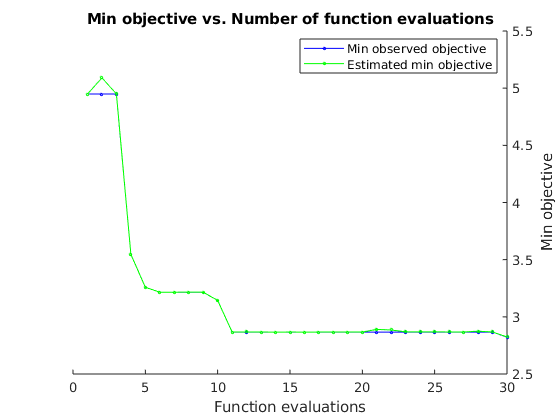

|=================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | NumVariables-|
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | ToSample     |
|=================================================================================================================================================================|
|    1 | Best   |      4.9487 |       9.948 |      4.9487 |      4.9487 |          Bag |          390 |            - |          115 |            2 |            6 |
|    2 | Accept |      7.0139 |      1.6731 |      4.9487 |      5.0903 |      LSBoost |           49 |    0.0036656 |           12 |          289 |            2 |
|    3 | Accept 

%Optimize Model Hyperparameters using bayesian inference (bayesopt)
%EnsembleTree
regressionEnsembleTopK = fitrensemble(topKpredictors, response, ...
    'Learners', template, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

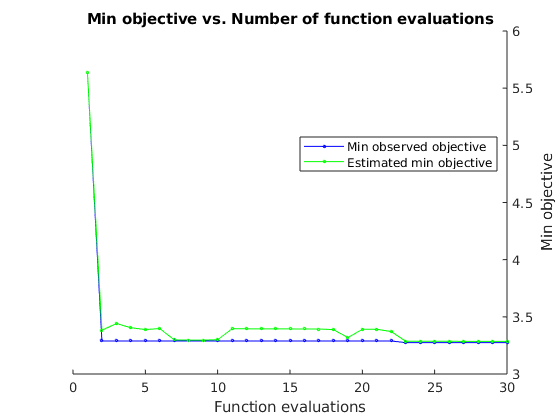

|==================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma | BasisFunction| KernelFuncti-|  KernelScale |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |      5.6369 |      4.2306 |      5.6369 |      5.6369 |       106.57 |     constant |     matern52 |       16.708 |        false |
|    2 | Best   |       3.289 |      24.689 |       3.289 |      3.3824 |       2.5555 | pureQuadrati | ardexponenti |            - |        false |
|    3 | Accept |      8.4557 |      3.9844 |       3.289 |      3.4417 |    0.0084291 |         none |   

%Gaussian Process Regressor
regressionGPTopK = fitrgp(topKpredictors, response, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

%Cross Validation Settings
crossValidationMethod = 'KFold';
crossValidationNumFolds = 5;
crossValidationLossFun = 'mse';

% Perform cross-validation
partitionedModel_RFTopK = crossval(regressionEnsembleTopK, crossValidationMethod, crossValidationNumFolds);
partitionedModel_GPTopK = crossval(regressionGPTopK, crossValidationMethod, crossValidationNumFolds);

% Compute validation predictions
validationPredictions_RF = kfoldPredict(partitionedModel_RFTopK);
validationPredictions_GP = kfoldPredict(partitionedModel_GPTopK);

% Compute validation RMSE
validationRMSE_RFTopK = sqrt(kfoldLoss(partitionedModel_RFTopK, 'LossFun', crossValidationLossFun));

validationRMSE_RFTopK = 4.1985

validationRMSE_GPTopK = sqrt(kfoldLoss(partitionedModel_GPTopK, 'LossFun', crossValidationLossFun));

validationRMSE_GPTopK = 4.9537

We can see that there is a drop is RMSE for the EnsembleTree Regressor however it is minimal. This tells us that the 5 most important features are capturing majority of the information within the dataset.

validationRMSE_RF, validationRMSE_RFTopK

validationRMSE_RF = 4.0370

validationRMSE_RFTopK = 4.1985

validationRMSE_GP, validationRMSE_GPTopK

validationRMSE_GP = 5.3497

validationRMSE_GPTopK = 4.9537

Interestingly we see a small performance drop for the EnsembleTree model when we use the top 5 important features however the performance of the gaussianProcess model is increased by ~ 0.5.